c_init = [1.44747036682991 340.409544320447 -53942.9013904458 4520022.47075240 -133170545.404650 -3822114.71912637];

b = optimresults.x

b = 	1.0e+10 *

    0.0000    0.0000   -0.0000    0.0014   -0.0915    2.2334


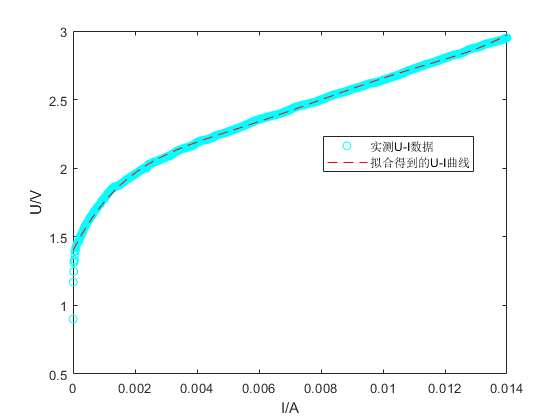

load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
I = I./1000;
Un = b(1) + b(2).*I + b(3).*I.^2 + b(4).*I.^3 + b(5).*I.^4 + b(6).*I.^5;
figure
plot(I, U, 'co')
hold on
plot(I, Un, '--r')
legend({'实测U-I数据', '拟合得到的U-I曲线'}, 'Location','best')
xlabel('I/A')
ylabel('U/V')
saveas(gcf, 'fig4.png');

% lambda = 0.327974911948322;
% Ith0 = 2.09792442194657E-05;
% Rth = 3593.49598351965;
% a_0 = 0.00245295354589810;
% a_1 = -2.24461489568760E-05;
% a_2 = 8.55495131262933E-08;
% a_3 = -3.04196846538548E-10;
% a_4 = 6.38679397411974E-13;
% i = 0.01;
% ui = b(1) + b(2).*i + b(3).*i.^2 + b(4).*i.^3 + b(5).*i.^4 + b(6).*i.^5;
% lambda.*Rth.*a_4.*t.^4 + lambda.*Rth.*a_3.*t.^3 + lambda.*Rth.*a_2.*t.^2 + (lambda.*Rth.*a_1 - 1).*t + 293.15 + Rth.*(lambda.*(Ith0 - i + a_0) + i.*ui) == 0

$$ans = \frac{3639991246326815\,t^{4}}{4835703278458516698824704}-\frac{423264838306279\,t^{3}}{1180591620717411303424}+\frac{7439693502048037\,t^{2}}{73786976294838206464}-\frac{4622740123177811\,t}{4503599627370496}+\frac{133605434115751223}{351843720888320}=0$$

t = sym('t')

$$t = t$$

% solve(lambda.*Rth.*a_4.*t.^4 + lambda.*Rth.*a_3.*t.^3 + lambda.*Rth.*a_2.*t.^2 + (lambda.*Rth.*a_1 - 1).*t + 293.15 + Rth.*(lambda.*(Ith0 - i + a_0) + i.*ui) == 0, t)

T =  293.15 + (0.011.*2.724578001 - 2.425319765e-3).*Rth

T = 392.1330

% load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
% load('D:\FOLDER\桌面\校数模\2017B\b.mat')
% lambda = 0.327974911948322;
% Ith0 = 2.09792442194657E-05;
% Rth = 3593.49598351965;
% a_0 = 0.00245295354589810;
% a_1 = -2.24461489568760E-05;
% a_2 = 8.55495131262933E-08;
% a_3 = -3.04196846538548E-10;
% a_4 = 6.38679397411974E-13;
% i = 0.011;
% t = 380.276;
% ui = b(1) + b(2).*i + b(3).*i.^2 + b(4).*i.^3 + b(5).*i.^4 + b(6).*i.^5;
% y = lambda.*Rth.*a_4.*t.^4 + lambda.*Rth.*a_3.*t.^3 + lambda.*Rth.*a_2.*t.^2 + (lambda.*Rth.*a_1 - 1).*t + 293.15 + Rth.*(lambda.*(Ith0 - i + a_0) + i.*ui)

y = 11.1586

clear all
global i;
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
I = I/1000;

Ti = [];
k = 0;
for i = 0:1e-4:0.0187
    k = k+1;
    Ti(k, 1:2) = [i fzero(@fitness_7, 350)];
end
Ti

Ti =          0  293.5082
    0.0000  293.5475
    0.0000  293.5871
    0.0000  293.6271
    0.0000  293.6674
    0.0001  293.7080
    0.0001  293.7489
    0.0001  293.7901
    0.0001  293.8316
    0.0001  293.8735


% fzero(@fitness_7, 350)

function y = fitness_7(t)
load('D:\FOLDER\桌面\校数模\2017B\L-I-20C.mat')
load('D:\FOLDER\桌面\校数模\2017B\b.mat')
global i;
lambda = 0.327974911948322;
Ith0 = 2.09792442194657E-05;
Rth = 3593.49598351965;
a_0 = 0.00245295354589810;
a_1 = -2.24461489568760E-05;
a_2 = 8.55495131262933E-08;
a_3 = -3.04196846538548E-10;
a_4 = 6.38679397411974E-13;
% i = 0.012;
% t = 380.276;
ui = b(1) + b(2).*i + b(3).*i.^2 + b(4).*i.^3 + b(5).*i.^4 + b(6).*i.^5;
y = lambda.*Rth.*a_4.*t.^4 + lambda.*Rth.*a_3.*t.^3 + lambda.*Rth.*a_2.*t.^2 + (lambda.*Rth.*a_1 - 1).*t + 293.15 + Rth.*(lambda.*(Ith0 - i + a_0) + i.*ui);
% y = abs(y);
end